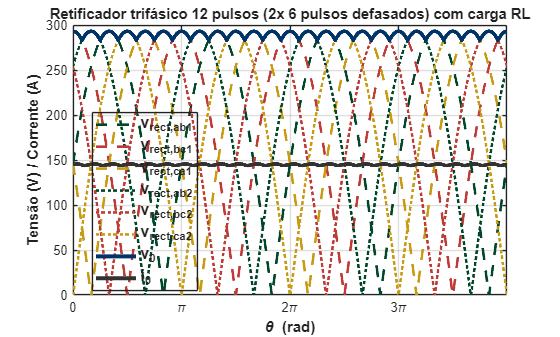

%% Retificador trifásico 12 pulsos (2 pontes de 6 pulsos defasadas de 30°) + carga RL

f     = 60;
Vm    = 170;
R     = 2;
L     = 1e-3;
Vd    = 0.7;
ncy   = 12;
fs    = 200e3;
shift = deg2rad(30);

series = false;

plotCycles = [10 11];

T     = 1/f;
dt    = 1/fs;
t     = 0:dt:(ncy*T);
omega = 2*pi*f;
theta = omega*t;

v_a1 = Vm*sin(theta);
v_b1 = Vm*sin(theta - 2*pi/3);
v_c1 = Vm*sin(theta + 2*pi/3);

v_ab1 = v_a1 - v_b1;
v_bc1 = v_b1 - v_c1;
v_ca1 = v_c1 - v_a1;

v_rect_ab1 = max(abs(v_ab1) - 2*Vd, 0);
v_rect_bc1 = max(abs(v_bc1) - 2*Vd, 0);
v_rect_ca1 = max(abs(v_ca1) - 2*Vd, 0);

v0_6_1 = max([v_rect_ab1; v_rect_bc1; v_rect_ca1], [], 1);

v_a2 = Vm*sin(theta + shift);
v_b2 = Vm*sin(theta + shift - 2*pi/3);
v_c2 = Vm*sin(theta + shift + 2*pi/3);

v_ab2 = v_a2 - v_b2;
v_bc2 = v_b2 - v_c2;
v_ca2 = v_c2 - v_a2;

v_rect_ab2 = max(abs(v_ab2) - 2*Vd, 0);
v_rect_bc2 = max(abs(v_bc2) - 2*Vd, 0);
v_rect_ca2 = max(abs(v_ca2) - 2*Vd, 0);

v0_6_2 = max([v_rect_ab2; v_rect_bc2; v_rect_ca2], [], 1);

if series
    v_0 = v0_6_1 + v0_6_2;
    i_bridge = [];
else
    v_0 = max(v0_6_1, v0_6_2);
end

i_0 = zeros(size(t));
for k = 2:numel(t)
    di_dt = (v_0(k) - R*i_0(k-1))/L;
    i_0(k) = i_0(k-1) + di_dt*dt;
    if i_0(k) < 0, i_0(k) = 0; end
end

if series
    i_1 = i_0;
    i_2 = i_0;
else
    i_1 = 0.5*i_0;
    i_2 = 0.5*i_0;
end

statale.maincolor = [0   51  102]/255;
statale.lilla     = [120 0   80 ]/255;
statale.darkgreen = [0   70  40 ]/255;
statale.red       = [190 60  55 ]/255;
statale.yellow    = [200 155 20 ]/255;
statale.grey      = [50 50 50]/255;

plotColors = [statale.maincolor; statale.lilla; statale.darkgreen; statale.red; statale.yellow];
set(groot,'defaultAxesColorOrder',plotColors);

LW  = 3.0;
LW2 = 2;
LW3 = 3;

c1 = plotCycles(1);  c2 = plotCycles(2);
t1 = (c1-1)*T;       t2 = c2*T;
idx = (t >= t1) & (t <= t2);

thetaP   = theta(idx);
thetaRel = thetaP - thetaP(1);

vab1P = v_ab1(idx); vbc1P = v_bc1(idx); vca1P = v_ca1(idx);
vab2P = v_ab2(idx); vbc2P = v_bc2(idx); vca2P = v_ca2(idx);

vrab1P = v_rect_ab1(idx); vrbc1P = v_rect_bc1(idx); vrca1P = v_rect_ca1(idx);
vrab2P = v_rect_ab2(idx); vrbc2P = v_rect_bc2(idx); vrca2P = v_rect_ca2(idx);

v0P = v_0(idx);
i0P = i_0(idx);

plot(thetaRel, vrab1P, '--', 'Color', plotColors(3,:), 'LineWidth', LW2); hold on;
plot(thetaRel, vrbc1P, '--', 'Color', plotColors(4,:), 'LineWidth', LW2);
plot(thetaRel, vrca1P, '--', 'Color', plotColors(5,:), 'LineWidth', LW2);

plot(thetaRel, vrab2P, ':', 'Color', plotColors(3,:), 'LineWidth', LW2);
plot(thetaRel, vrbc2P, ':', 'Color', plotColors(4,:), 'LineWidth', LW2);
plot(thetaRel, vrca2P, ':', 'Color', plotColors(5,:), 'LineWidth', LW2);

plot(thetaRel, v0P, 'Color', plotColors(1,:), 'LineWidth', LW3);
plot(thetaRel, i0P, 'Color', statale.grey, 'LineWidth', LW3);

grid on;
xlabel('\theta (rad)');
ylabel('Tensão (V) / Corrente (A)');
title('Retificador trifásico 12 pulsos (2x 6 pulsos defasados) com carga RL');

xlim([0, thetaRel(end)]);
k2 = floor(thetaRel(end)/pi);
xt = (0:k2)*pi;
xticks(xt);

m = 0:k2;
labs = strings(size(m));
for kk = 1:numel(m)
    if m(kk) == 0
        labs(kk) = "0";
    elseif m(kk) == 1
        labs(kk) = "\pi";
    else
        labs(kk) = sprintf('%g\\pi', m(kk));
    end
end
xticklabels(labs);

lgd = legend( ...
 'v_{rect,ab1}','v_{rect,bc1}','v_{rect,ca1}', ...
 'v_{rect,ab2}','v_{rect,bc2}','v_{rect,ca2}', ...
 'v_0','i_0', ...
 'Location','best');
lgd.FontSize   = 12;
lgd.FontWeight = 'bold';
lgd.Color      = 'none';

ax = gca;
ax.XLabel.FontWeight = 'bold';
ax.YLabel.FontWeight = 'bold';

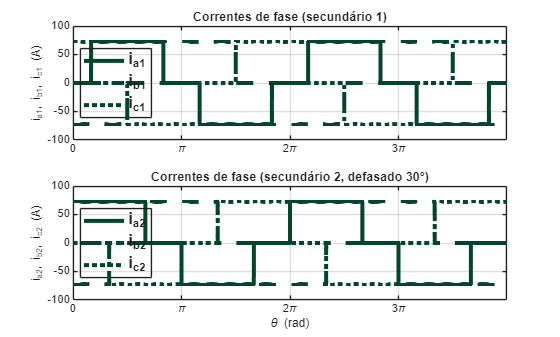


Vmat1 = [v_a1; v_b1; v_c1];
[~, idxMax1] = max(Vmat1, [], 1);
[~, idxMin1] = min(Vmat1, [], 1);

i_a1 = zeros(size(t)); i_b1 = zeros(size(t)); i_c1 = zeros(size(t));
i_a1(idxMax1==1) =  i_1(idxMax1==1);  i_a1(idxMin1==1) = -i_1(idxMin1==1);
i_b1(idxMax1==2) =  i_1(idxMax1==2);  i_b1(idxMin1==2) = -i_1(idxMin1==2);
i_c1(idxMax1==3) =  i_1(idxMax1==3);  i_c1(idxMin1==3) = -i_1(idxMin1==3);

Vmat2 = [v_a2; v_b2; v_c2];
[~, idxMax2] = max(Vmat2, [], 1);
[~, idxMin2] = min(Vmat2, [], 1);

i_a2 = zeros(size(t)); i_b2 = zeros(size(t)); i_c2 = zeros(size(t));
i_a2(idxMax2==1) =  i_2(idxMax2==1);  i_a2(idxMin2==1) = -i_2(idxMin2==1);
i_b2(idxMax2==2) =  i_2(idxMax2==2);  i_b2(idxMin2==2) = -i_2(idxMin2==2);
i_c2(idxMax2==3) =  i_2(idxMax2==3);  i_c2(idxMin2==3) = -i_2(idxMin2==3);

ia1P = i_a1(idx); ib1P = i_b1(idx); ic1P = i_c1(idx);
ia2P = i_a2(idx); ib2P = i_b2(idx); ic2P = i_c2(idx);

figure('Color','w');

axA = subplot(2,1,1);
plot(thetaRel, ia1P, 'Color', plotColors(3,:), 'LineWidth', LW); hold on;
plot(thetaRel, ib1P, '--', 'Color', plotColors(3,:), 'LineWidth', LW);
plot(thetaRel, ic1P, ':', 'Color', plotColors(3,:), 'LineWidth', LW);
grid on;
title('Correntes de fase (secundário 1)');
ylabel('i_{a1}, i_{b1}, i_{c1} (A)');
xlim([0, thetaRel(end)]);
xticks(xt); xticklabels(labs);

lg1 = legend('i_{a1}','i_{b1}','i_{c1}','Location','best');
lg1.FontSize = 12; lg1.FontWeight='bold'; lg1.Color='none';

axB = subplot(2,1,2);
plot(thetaRel, ia2P, 'Color', plotColors(3,:), 'LineWidth', LW); hold on;
plot(thetaRel, ib2P, '--', 'Color', plotColors(3,:), 'LineWidth', LW);
plot(thetaRel, ic2P, ':', 'Color', plotColors(3,:), 'LineWidth', LW);
grid on;
title('Correntes de fase (secundário 2, defasado 30°)');
ylabel('i_{a2}, i_{b2}, i_{c2} (A)');
xlabel('\theta (rad)');
xlim([0, thetaRel(end)]);
xticks(xt); xticklabels(labs);

lg2 = legend('i_{a2}','i_{b2}','i_{c2}','Location','best');
lg2.FontSize = 12; lg2.FontWeight='bold'; lg2.Color='none';

linkaxes([axA axB],'x');

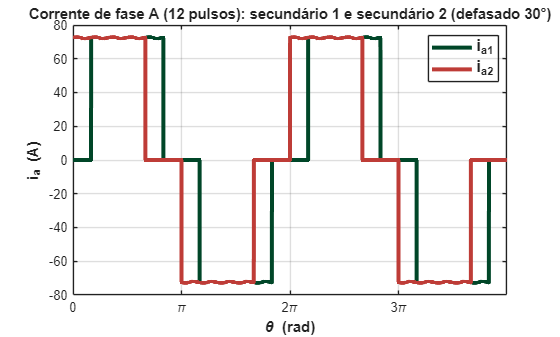


figure('Color','w');
plot(thetaRel, ia1P, 'Color', plotColors(3,:), 'LineWidth', LW); hold on;
plot(thetaRel, ia2P, 'Color', plotColors(4,:), 'LineWidth', LW);
grid on;

xlabel('\theta (rad)');
ylabel('i_a (A)');
title('Corrente de fase A (12 pulsos): secundário 1 e secundário 2 (defasado 30°)');

xlim([0, thetaRel(end)]);
xticks(xt);
xticklabels(labs);

lgdA12 = legend('i_{a1}','i_{a2}', 'Location','best');
lgdA12.FontSize   = 12;
lgdA12.FontWeight = 'bold';
lgdA12.Color      = 'none';

axA12 = gca;
axA12.XLabel.FontWeight = 'bold';
axA12.YLabel.FontWeight = 'bold';